# Lecture 14: Playing with the model for the Speech 

In this lecture we are gonna play around with the modeling for speech and will work around with the LPC (Linear Predictive Coding)  coefficients

## Model For Speech Generation

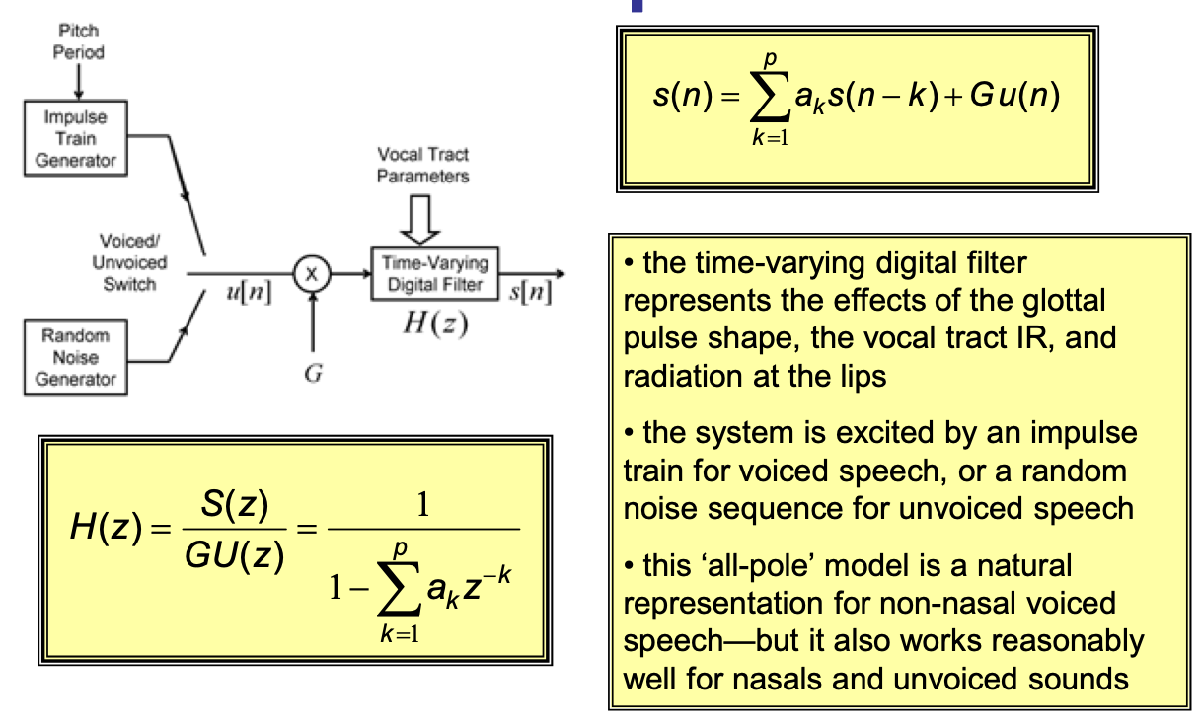

## From the Previous Lecture

Fs=8000;
load a.mat

Error using load
Unable to read file 'a.mat'. No such file or directory.

y=a;
N = length(y);

t = (0:N-1)/Fs; % Time Vector
y = y-mean(y); % Substracting the mean value for the signal
%y = y./max(y);

% Plotting the signal
figure, plot(t,y)
xlabel('time [s]')
ylabel('Amplitude [a.u.]')
title('Voice Signal Pronouncing the Vowel A')
grid on

% Computing the PSD
[Pxx,F]= pwelch(y,[],[],[],Fs,'psd');
Pxx = Pxx*Fs*2*pi; % Converting to normal PSD and not power per rad per sample
figure, semilogy(F,Pxx) % Plotting the PSD in a semilog y axis
xlabel('Frequency [Hz]')
ylabel('Amplitude dB')
grid on
xlim([0 max(F)])
title('PSD for the voice signal')

% Computing the autocorrelation function
ACF_y = xcorr(y,y,'normalized'); % obtaining the normalized autocorrelation coefficients
ACF_y(1:N-1)=[]; % Eliminating the first elements, only interesdes in the positive lags.
figure, plot(t,ACF_y) % Plotting the ACF
xlabel('lag [s]')
ylabel('Autocorrelation [n.u.]')
grid on
xlim([0 max(t)])
title('AutoCorrelation Function')

% Computing the error and the coefficients using the levisson-Durbin
% algorithm

max_p = 100; % Selecting the maximal order model to try, in order to find the optimal.
I = zeros(1,max_p); % Initializinfg the Akaike Criteria vector
e = zeros(1,max_p); % Initializing the error vector
for p = 1:max_p
    [~,e(p)] = levinson(ACF_y,p); % Solving the normilized equations using the Levinsson-Durbin Algorithm
    I(p) = log10(e(p))+(2*p)/(N*0.02); % Finding th eAKAIKE criteria taking a window of 20ms where the signal is stationary
end

% Ploting the evolution of the error
figure, plot(1:max_p,e,'LineWidth',2)
xlabel('Model Order P')
ylabel('Error')
grid on
xlim([0 max_p])
title('Error Evolution')

% Plotting the AKAIKE criteria
figure, plot(1:max_p,I,'LineWidth',2)
xlabel('Model Order P')
ylabel('Akaike Criteria')
grid on
xlim([0 max_p])
title('Model Error vs Model Complexity')

%% Constructing the spectrum using the optimal model order

P_op =  20;
[a,E] = levinson(ACF_y,P_op); % CSolving the normiliozed equations and computing the respective error
% (This a coefficients model the vocal track when pronouncing the vowel a.

[Pxx_e,F2]=freqz(E/sqrt(2),a,length(F),Fs); % Finding the frequency response, using as gain E^2/2.
Pxx_2 = conj(Pxx_e).*Pxx_e;
figure, semilogy(F2,Pxx_2,'LineWidth',2) % Plotting the power spectral density
xlabel('Frequency [Hz]')
ylabel('Amplitude [dB]')
grid on
xlim([0 max(F2)])
title ('Estimated Model PSD')

% Comparing both approaches

figure, semilogy(F,Pxx)
xlabel('Frequency [Hz]')
ylabel('Amplitude dB')
grid on
xlim([0 max(F)])
hold on
semilogy(F2,Pxx_2,'r','LineWidth',2)
title('non-parametric vs parametric PSD')
legend('non-parametric PSD','parametric PSD')

% Computing the impulse response
[Pxx_whole,F2_n]=freqz(E/sqrt(2),a,length(F),Fs,'whole'); % computing the spectrum for the whole frequency range to compute the inverse
h = real(ifft(Pxx_whole));

% Plotting the Impulse response of the system
figure, plot((0:length(h)-1)/Fs,h,v,'LineWidth',2)
xlabel('time [s]')
ylabel('Amplitude [a.u.]')
grid on
xlim([0 (length(h)-1)/Fs])
title('Impulse Response from Model')

% How does it sound?

sound(h./max(h),Fs)

%% Using the model to generate a voice pronouncing the vowel a. So far the model 
%% Indicate the impulse response of the vcal track, the generation of voice occur when
%% The vocal tracjk is excited by a train of impulses.

% Lets find the distances between the peaks in the PSD
figure, semilogy(F,Pxx)
xlabel('Frequency [Hz]')
ylabel('Amplitude dB')
grid on
xlim([0 max(F)])
title('Non-Parametric PSD')

Dis_F = 147.7; % Distance between two peaks in the frequency domain 
T_pulses = 1/Dis_F; % Distances of the train of impulses in the time domain
samples = fix(T_pulses*Fs); % Number of samples when these impulses occur

x = zeros(1,2*Fs); % Generating a vector of length 2 seconds
x(1:samples:end) = 1; % Generating a train of impulses with periodicity equatl to samples
figure, stem(t,x)
xlabel('time [s]')
ylabel('Amplitude [a.u.]')
grid on
xlim([0 2])
ylim([-0.1 1.1])
title('Escitation signal to the vocal track')

% Finding the output of the system when it is excited by the train of
% impulses (the output should be the pronunciation of the vowel a.

y_e = conv(x,h); % convolving the impulse train with the impulse response of my vocal track
y_e = y_e./max(y_e); % Normalaizing
y_e = y_e(length(h):end-length(h)); % Eliminating the first elements corresponding to the transient response
figure, plot((0:length(y_e)-1)/Fs,y_e) % Plotting the estimated signal (me pronouncing the a vowel)
xlabel('time [s]')
ylabel('Amplitude [a.u.]')
grid on
xlim([0 2])
ylim([-0.8 1.1])
title('Estimated signal producing vowel a')
% How does it sound?
sound(y_e,Fs)

% Lets estimate the impulse response from the nonparametric transfer
% function.

[Pxx_all,F]= pwelch(y,[],[],[],Fs,'twosided');
h_n = real(ifft(Pxx_all*2*pi*Fs));

figure, plot((0:length(h_n)-1)/Fs,h_n)
xlabel('time [s]')
ylabel('Amplitude [a.u.]')
grid on
xlim([0 (length(h_n)-1)/Fs])
title('Impulse Response from Model')

y_e2 = conv(x,h_n);
y_e2 = y_e2./max(y_e2); % Normalaizing
y_e2 = y_e2(length(h_n):end-length(h_n)); % Eliminating the first elements corresponding to the transient response

figure, plot((0:length(h_n)-1)/Fs,h_n)
xlabel('time [s]')
ylabel('Amplitude [a.u.]')
grid on
xlim([0 (length(h_n)-1)/Fs])
title('Impulse Response from non-Parametric model')

figure, plot((0:(length(y_e2)-1))/Fs,y_e2)
xlabel('time [s]')
ylabel('Amplitude [a.u.]')
grid on
xlim([0 (length(y_e2)-1)/Fs])
ylim([-1.0 0.6])
title('Estimated signal producing vowel a')

% How does it sound?
sound(y_e2(length(h_n):end-length(h_n))/max(y_e2(length(h_n):end-length(h_n))))


## Comparisson of the models for different Vowels

Loading the signals

Fs=8000;
aux_a = load('a.mat');
a = aux_a.y;
aux_e = load('e.mat');
e = aux_e.y;
aux_i = load('i.mat');
i = aux_i.y;
aux_o = load('o.mat');
o = aux_o.y;
aux_u = load('u.mat');
u = aux_u.y;

N = length(a);

t = (0:N-1)/Fs; % Time Vector
a = a-mean(a); % Substracting the mean value for the signal
e = e-mean(e); % Substracting the mean value for the signal
i = i-mean(i); % Substracting the mean value for the signal
o = o-mean(o); % Substracting the mean value for the signal
u = u-mean(u); % Substracting the mean value for the signal


## Non-Parametric Approach

% PSD for the A sound
[Pxx_a,F]= pwelch(a,[],[],[],Fs,'psd');
Pxx_a = Pxx_a*Fs*2*pi; % Converting to normal PSD and not power per rad per sample

% PSD for the E sound
[Pxx_e]= pwelch(e,[],[],[],Fs,'psd');
Pxx_e = Pxx_e*Fs*2*pi; % Converting to normal PSD and not power per rad per sample

% PSD for the I sound
[Pxx_i]= pwelch(i,[],[],[],Fs,'psd');
Pxx_i = Pxx_i*Fs*2*pi; % Converting to normal PSD and not power per rad per sample

% PSD for the O sound
[Pxx_o]= pwelch(o,[],[],[],Fs,'psd');
Pxx_o = Pxx_o*Fs*2*pi; % Converting to normal PSD and not power per rad per sample

% PSD for the U sound
[Pxx_u]= pwelch(u,[],[],[],Fs,'psd');
Pxx_u = Pxx_u*Fs*2*pi; % Converting to normal PSD and not power per rad per sample

figure, semilogy(F,Pxx_a,'LineWidth',2) % Plotting the PSD in a semilog y axis
hold on
semilogy(F,Pxx_e,'LineWidth',2)
semilogy(F,Pxx_i,'LineWidth',2)
semilogy(F,Pxx_o,'LineWidth',2)
semilogy(F,Pxx_u,'LineWidth',2)

xlabel('Frequency [Hz]')
ylabel('Amplitude dB')
grid on
xlim([0 max(F)])
title('Non Parametric PSD for the Different Vowels')
legend('PSD for vowel a','PSD for vowel e','PSD for vowel i','PSD for vowel o','PSD for vowel u')

## Parametric Approach

P_op =  60;

% Computing the spectrum for the a
ACF_a = xcorr(a,a,'normalized'); % obtaining the normalized autocorrelation coefficients
ACF_a(1:N-1)=[]; % Eliminating the first elements, only interesdes in the positive lags.
[aa,Ea] = levinson(ACF_a,P_op); % Solving the normalized equations and computing the respective error
[Pxx_a2,F_2]=freqz(Ea/sqrt(2),aa,length(F),Fs); % Finding the frequency response, using as gain E^2/2.
Pxx_a2 = conj(Pxx_a2).*Pxx_a2;

% Computing the spectrum for the a
ACF_e = xcorr(e,e,'normalized'); % obtaining the normalized autocorrelation coefficients
ACF_e(1:N-1)=[]; % Eliminating the first elements, only interesdes in the positive lags.
[ae,Ee] = levinson(ACF_e,P_op); % Solving the normalized equations and computing the respective error
[Pxx_e2]=freqz(Ee/sqrt(2),ae,length(F),Fs); % Finding the frequency response, using as gain E^2/2.
Pxx_e2 = conj(Pxx_e2).*Pxx_e2;

% Computing the spectrum for the a
ACF_i = xcorr(i,i,'normalized'); % obtaining the normalized autocorrelation coefficients
ACF_i(1:N-1)=[]; % Eliminating the first elements, only interesdes in the positive lags.
[ai,Ei] = levinson(ACF_i,P_op); % Solving the normalized equations and computing the respective error
[Pxx_i2]=freqz(Ei/sqrt(2),ai,length(F),Fs); % Finding the frequency response, using as gain E^2/2.
Pxx_i2 = conj(Pxx_i2).*Pxx_i2;

% Computing the spectrum for the a
ACF_o = xcorr(o,o,'normalized'); % obtaining the normalized autocorrelation coefficients
ACF_o(1:N-1)=[]; % Eliminating the first elements, only interesdes in the positive lags.
[ao,Eo] = levinson(ACF_o,P_op); % Solving the normalized equations and computing the respective error
[Pxx_o2]=freqz(Eo/sqrt(2),ao,length(F),Fs); % Finding the frequency response, using as gain E^2/2.
Pxx_o2 = conj(Pxx_o2).*Pxx_o2;

% Computing the spectrum for the a
ACF_u = xcorr(u,u,'normalized'); % obtaining the normalized autocorrelation coefficients
ACF_u(1:N-1)=[]; % Eliminating the first elements, only interesdes in the positive lags.
[au,Eu] = levinson(ACF_u,P_op); % Solving the normalized equations and computing the respective error
[Pxx_u2]=freqz(Eu/sqrt(2),au,length(F),Fs); % Finding the frequency response, using as gain E^2/2.
Pxx_u2 = conj(Pxx_u2).*Pxx_u2;

%ploting the spectrums

figure, semilogy(F_2,Pxx_a2,'LineWidth',2) % Plotting the PSD in a semilog y axis
hold on
semilogy(F_2,Pxx_e2,'LineWidth',2)
semilogy(F_2,Pxx_i2,'LineWidth',2)
semilogy(F_2,Pxx_o2,'LineWidth',2)
semilogy(F_2,Pxx_u2,'LineWidth',2)

xlabel('Frequency [Hz]')
ylabel('Amplitude dB')
grid on
xlim([0 max(F)])
title('Parametric PSD for the Different Vowels')
legend('PSD for vowel a','PSD for vowel e','PSD for vowel i','PSD for vowel o','PSD for vowel u')


## Comparisson between different speakers

Comparing my pronunciation of the a vowel with th epronunciation from another speaker. Both signals have the same frequency aand the samenumber of samples, to facilitate the processing.

load a_R.mat

a_R = a_R./max(abs(a_R));
a_R = a_R -mean(a_R);

% Non-parametric PSD for the A sound
[Pxx_aR,F]= pwelch(a_R,[],[],[],Fs,'psd');
Pxx_aR = Pxx_aR*Fs*2*pi; % Converting to normal PSD and not power per rad per sample

figure, semilogy(F,Pxx_a,'LineWidth',2) % Plotting the PSD in a semilog y axis
hold on
semilogy(F,Pxx_aR,'LineWidth',2)

xlabel('Frequency [Hz]')
ylabel('Amplitude dB')
grid on
xlim([0 max(F)])
title('Non Parametric PSD for Different Speaker pronouncing the a vowel')
legend('My vowel a','Someone else vowel a')

% Parametric PSD
ACF_aR = xcorr(a_R,a_R,'normalized'); % obtaining the normalized autocorrelation coefficients
ACF_aR(1:N-1)=[]; % Eliminating the first elements, only interesdes in the positive lags.
[aaR,EaR] = levinson(ACF_aR,P_op); % Solving the normalized equations and computing the respective error
[Pxx_aR2]=freqz(EaR/sqrt(2),aaR,length(F),Fs); % Finding the frequency response, using as gain E^2/2.
Pxx_aR2 = conj(Pxx_aR2).*Pxx_aR2;

figure, semilogy(F_2,Pxx_a2,'LineWidth',2) % Plotting the PSD in a semilog y axis
hold on
semilogy(F_2,Pxx_aR2,'LineWidth',2)

xlabel('Frequency [Hz]')
ylabel('Amplitude dB')
grid on
xlim([0 max(F)])
title('Parametric PSD for Different Speaker pronouncing the a vowel')
legend('My vowel a','Someone else vowel a')


## Small Excercise for differienciating between vowels

Calculate LPC coefficients and make a cluster analysis

P_order = 5;

% Partitioning the data in segments of 20ms and an overlap of 10ms

Xa = particionar(a,Fs,10,20);
Xe = particionar(e,Fs,10,20);
Xi = particionar(i,Fs,10,20);
Xo = particionar(o,Fs,10,20);
Xu = particionar(u,Fs,10,20);

% Computing LPC coeff
Xa = Xa - ones(size(Xa,1),1)*mean(Xa);
Xe = Xe - ones(size(Xe,1),1)*mean(Xe);
Xi = Xi - ones(size(Xi,1),1)*mean(Xi);
Xo = Xo - ones(size(Xo,1),1)*mean(Xo);
Xu = Xu - ones(size(Xu,1),1)*mean(Xu);

LPC_a = lpc(Xa,P_order);
LPC_e = lpc(Xe,P_order);
LPC_i = lpc(Xi,P_order);
LPC_o = lpc(Xo,P_order);
LPC_u = lpc(Xu,P_order);

LPC_vowels = [LPC_a;LPC_e;LPC_o;LPC_u];

idx = kmeans(LPC_vowels(:,2:end),5);
figure,  silhouette(LPC_vowels,idx)
figure, plot(idx);

[coeff,score,latent] = pca(LPC_vowels(:,2:end));
recons_3 = score*coeff(1:3,:)';

figure, plot3(recons_3(idx==1,1),recons_3(idx==1,2),recons_3(idx==1,3),'rx');
hold on, plot3(recons_3(idx==2,1),recons_3(idx==2,2),recons_3(idx==2,3),'go');
plot3(recons_3(idx==3,1),recons_3(idx==3,2),recons_3(idx==3,3),'b*');
plot3(recons_3(idx==4,1),recons_3(idx==4,2),recons_3(idx==4,3),'m.');
plot3(recons_3(idx==5,1),recons_3(idx==5,2),recons_3(idx==5,3),'k+');


grid on
xlabel('Reconstruct 1st PCA')
ylabel('Reconstruct 1st PCA')
zlabel('Reconstruct 1st PCA')

title('Cluster for the Different Vowels')
%legend('Cluster 1 = o','Cluster 2 = i','Cluster 3 =a','Cluster 4 =u','Cluster 5 =e')